## Setting the number of followers

clear
clc
number_of_followers = 6;
number_of_virtual = 1;
rng(1555)

deltat = 0.01;
time_steps = 1:deltat:100+0.99;
r0 = [time_steps;time_steps+sin(time_steps)].';
r0 = horzcat(r0,zeros(size(r0)))

r0 =     1.0000    1.8415         0         0
    1.0100    1.8568         0         0
    1.0200    1.8721         0         0
    1.0300    1.8873         0         0
    1.0400    1.9024         0         0
    1.0500    1.9174         0         0
    1.0600    1.9324         0         0
    1.0700    1.9472         0         0
    1.0800    1.9620         0         0
    1.0900    1.9766         0         0


r0_reshaped = zeros(1,4);
r0_reshaped(1,:) =r0(1,:);

for i=2:size(r0,1)    
    r0(i,3:4) = (r0(i,1:2)-r0(i-1,1:2))/deltat;
    r0_reshaped(:,:,i) = r0(i,:);
end
r0_reshaped;

random_coords = randn(number_of_followers,4);
r_i = zeros(number_of_followers+number_of_virtual,4,size(time_steps,2));
r_i(2:end,:,1)= [random_coords(:,1)-5 random_coords(:,2)-5 random_coords(:,3)*0 random_coords(:,4)*0];
r_i(1,:,:) = r0_reshaped;
size(r_i);

% plot(reshape(r_i(1,:,:),100,2))

adj_matrix = [0 1 0 0 0 0 0;
              1 0 1 0 0 0 1;
              0 1 0 1 0 0 0;
              0 0 1 0 1 0 0;
              0 0 0 1 0 1 0;
              0 0 0 0 1 0 1;
              0 1 0 0 0 1 0];
r_i(2:end,1:2,1) = [-8 2;
                -3 5;
                2 -8;
                3 -9;
                5 -5;
                5 2];

G = graph(adj_matrix,{'leader','1','2','3','4','5','6'})

G =   graph with properties:

    Edges: [7×2 table]
    Nodes: [7×1 table]


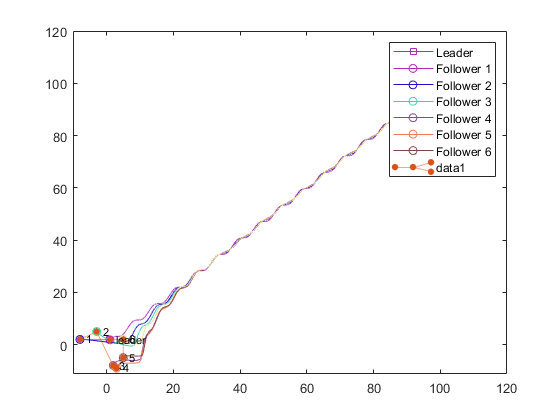

plot(G,'XData',r_i(:,1,1),'YData',r_i(:,2,1))

## Where $\dot{r}_i = u_i$ and $\dot{v_i} = u_i$

## 
$$u_i = -\sum_{j=0}^na_{ij}[(r_i-r_j)+\alpha (v_i-v_j)]-\beta sgn[\sum_{j=0}^na_{ij}[\gamma(r_i-r_j)+(v_i-v_j)]]$$


## 
$$\tilde{\dot{r}}_i = r_i - r_0$$


alpha = 1;
beta = 5;
gamma = 1;

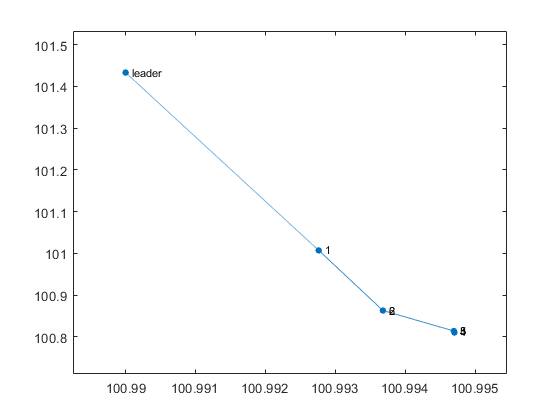

v_dot = zeros(number_of_followers,2);
for t=1:size(r_i,3)
    for i=2:size(r_i,1)
        temp_sum = 0;
        temp_sum1 = 0;
        for j=1:size(r_i,1)
            r_tilde = r_i(i,1:2,t)-r_i(j,1:2,t);
            v_tilde = r_i(i,3:4,t)-r_i(j,3:4,t);
            temp_sum = temp_sum + adj_matrix(i,j)*(r_tilde+alpha*v_tilde);
            temp_sum1 = temp_sum1+adj_matrix(i,j)*(gamma*r_tilde+v_tilde);
        end
        v_dot(i-1,:) = -temp_sum - beta*sign(temp_sum1);
    end
    r_i(2:end,3:4,t+1) = r_i(2:end,3:4,t)+(v_dot*deltat);
    r_i(2:end,1:2,t+1) = r_i(2:end,1:2,t)+(r_i(2:end,3:4,t)*deltat);
%    plot(G,'XData',r_i(:,1,t),'YData',r_i(:,2,t),"NodeLabel",{'leader','1','2','3','4','5','6'});
%    pause(0.005)
end

% r_i(:,:,end)=[];
% save("ConsensustrackingDynamics","r_i")

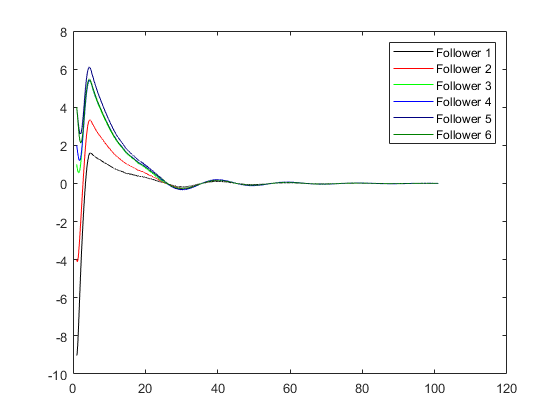

load("ConsensustrackingDynamics.mat","r_i")
clf
colorrand =[0 0 0;1 0 0;0 1 0;0 0 1;0 0 0.5;0 0.5 0;0.5 0 0];
for i=1:6
    plot(time_steps,reshape(r_i(i+1,1,:)-r_i(1,1,:),[],1),"Color",colorrand(i,:))    
    hold on
end
legend(["Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])
clf
hold on

for i=1:6
    plot(time_steps,reshape(r_i(i+1,2,:)-r_i(1,2,:),[],1),"Color",colorrand(i,:))    
    hold on
end
legend(["Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])

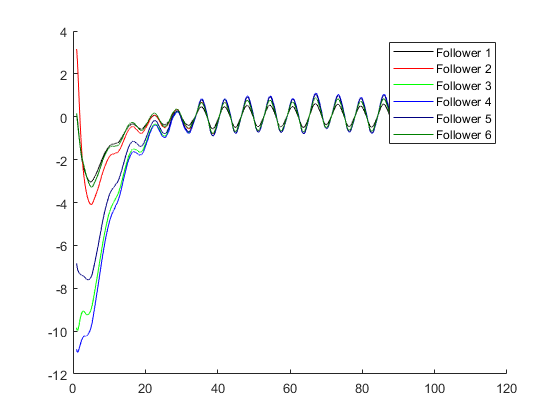

clf

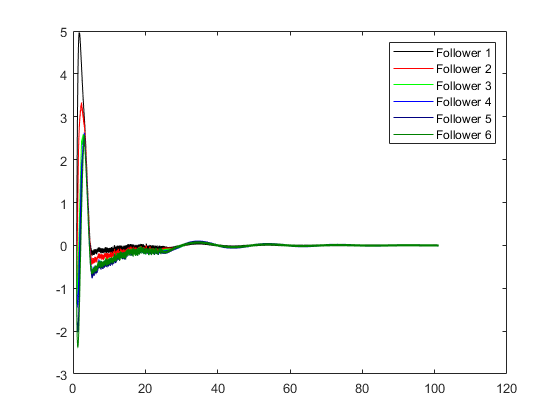

for i=1:6
    plot(time_steps,reshape(r_i(i+1,3,:)-r_i(1,3,:),[],1),"Color",colorrand(i,:))    
    hold on
end
legend(["Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])
clf
hold on

for i=1:6
    plot(time_steps,reshape(r_i(i+1,4,:)-r_i(1,4,:),[],1),"Color",colorrand(i,:))    
    hold on
end
legend(["Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])

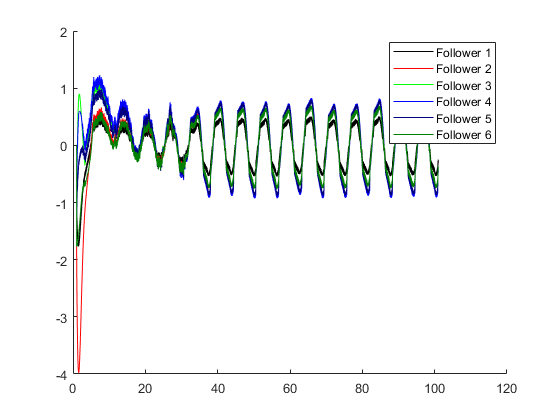

clf

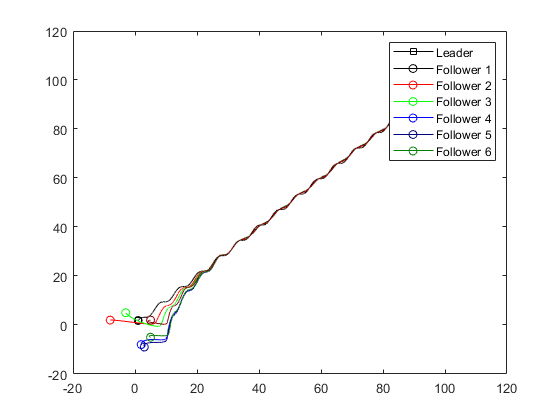

    plot(reshape(r_i(1,1,:),[],1),reshape(r_i(1,2,:),[],1),"Color",colorrand(1,:),"Marker","square","MarkerIndices",1)
hold on
for i=1:7
    plot(reshape(r_i(i,1,:),[],1),reshape(r_i(i,2,:),[],1),"Color",colorrand(i,:),"Marker","o","MarkerIndices",1)
end
legend(["Leader","Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])
